%terrain correction tc
%creating extended grid
T = readtable('Q1/RESOURCES/NGS_GRAVD_Block_CN03_BETA1/NGS_GRAVD_Block_CN03_Gravity_Data_BETA1.txt')

T = 125431×6 table
       Var1        Var2      Var3      Var4       Var5        Var6   
    ___________    _____    ______    _______    ______    __________

    {'CN03101'}    49730    42.971    -96.738    6364.3    9.7849e+05
    {'CN03101'}    49731    42.971     -96.74    6364.6    9.7849e+05
    {'CN03101'}    49732    42.971    -96.742    6364.9    9.7849e+05
    {'CN03101'}    49733    42.971    -96.743    6365.4    9.7849e+05
    {'CN03101'}    49734    42.971    -96.745    6365.8    9.7849e+05
    {'CN03101'}    49735    42.971    -96.747    6366.3    9.7849e+05
    {'CN03101'}    49736    42.971    -96.748    6366.6    9.7849e+05
    {'CN03101'}    49737    42.971     -96.75    6366.8    9.7849e+05
    {'CN03101'}    49738    42.971    -96.752    6366.8    9.7849e+05
    {'

latitude1 = T.Var3;
longitude1 = T.Var4;
max_lon = max(longitude1)

max_lon = -95.8782

min_lon = min(longitude1)

min_lon = -102.9637

max_lat = max(latitude1)

max_lat = 43.0189

min_lat = min(latitude1)

min_lat = 40.0908

err = 0.6

err = 0.6000

lat = min(latitude1)+err:0.01:max(latitude1)-err;
long = min(longitude1)+err:0.01:max(longitude1)-err;
[Longitude_grid,Latitude_grid]=meshgrid(long,lat);

%getting and setting DEM Heights
files = ['Q7/srtm_16_04/srtm_16_04.asc';'Q7/srtm_17_04/srtm_17_04.asc'];
Hs = combine_DEM_data(files,Latitude_grid,Longitude_grid);

tc2 =  terrain_correction(Hs,Latitude_grid1,Longitude_grid,0.01);

Determining spatial grids
Setting up integration kernel
FFT kernel for TC
FFT H^2
FFT H
FFT ones
Computing TC


%% do some plotting and save the output
    disp('Plotting')

Plotting


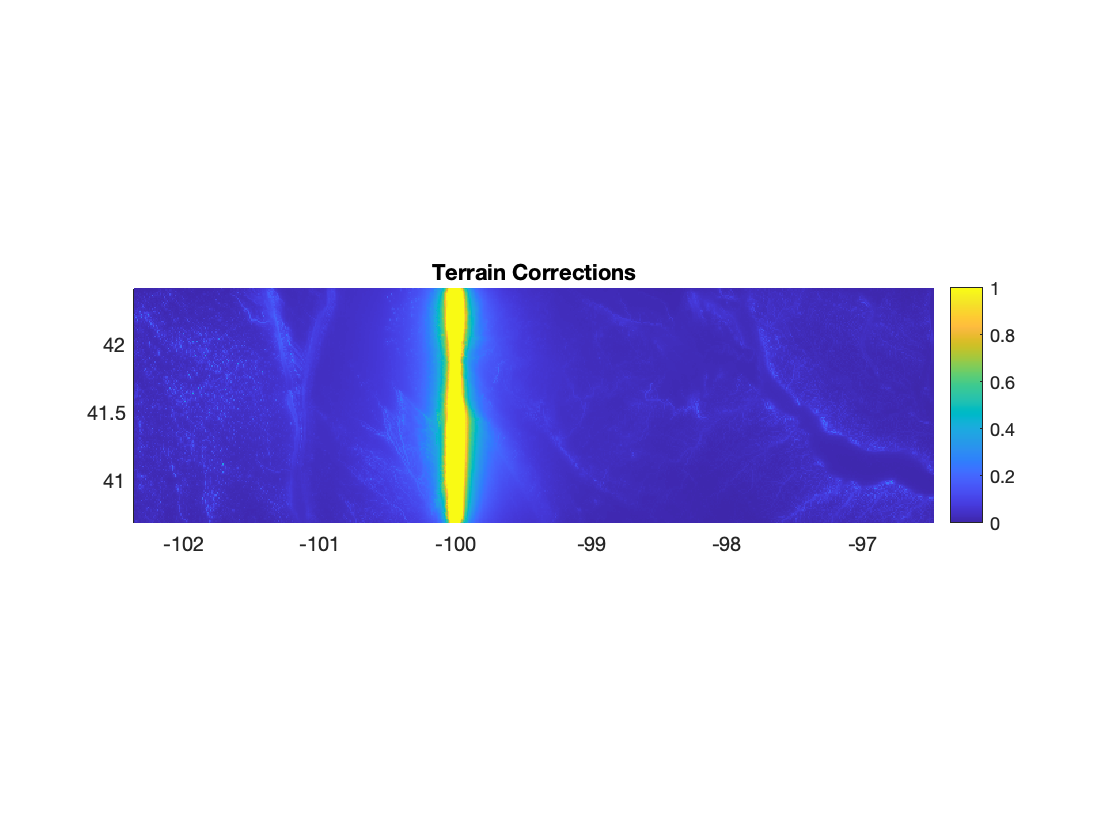

    figure(1)
    clf
    hold on
    imagesc(long,lat,tc2)
    caxis([0 1])
    axis equal
    axis tight
    title('Terrain Corrections')
    colorbar

    drawnow
    toc

Elapsed time is 2826.795475 seconds.


function H1 = addPadding_full(H)

  terrain_correction(H,lat,long,res) calculates terrain correction using 
  convolution integral 
   INPUT:
    1 - H DEM heights calculated using combine_DEM_data



    sizeH = size(H);
    zeroH = zeros(sizeH);
  %  H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
     H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end